# ENGR105    ---    Problem Set 10    ---   Image processing 

## Due: Friday, 11/13/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW9.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu. **Please also see my recent email regarding alternative methods for exporting to PDF.**

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Gain familiarity importing, manipulating, and analyzing images.

- Gain familiarity analyzing experimental data.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (60 pts): Final project proposal

**Please read through the Final Project Proposal on Canvas, and submit your proposal by ****Monday, November 16th****.**

https://canvas.upenn.edu/courses/1541333/assignments/8473178?module_item_id=19410925

**Note**: the deadline for this homework set (*i.e.* Problem 2), is Friday, November 13th, as mentioned above. You have until the following Monday to submit the proposal as a PDF document. 

**Note:** if you submit an appropriate document on time, you will receive all points for this problem.

## PROBLEM 2 (40 pts): Image processing

*Microfluidics* refers to the study of fluid flow occuring on *sub-millimeter* length scales and encompasses aspects of engineering, physics, chemistry, biochemistry, nanotechnology, and biotechnology. Common applications of microfluidic technology include *inkjet printing,* medical devices for *disease diagnostics*, and* fuel cells* and energy technology*.*

Multiple labs at Penn and many research investigators around the world use microfluidic systems to study the fundamental behavior of fluidics and interfaces and to invent new technologies. In my research at Penn, I am interested in studying the transfer of fluid into flowing microdroplets, which has potential applications including ultrafast, ultrasensitive molecular diagnostics and screenings. A setup that I use for a typical microfluidics experiment is shown below. 

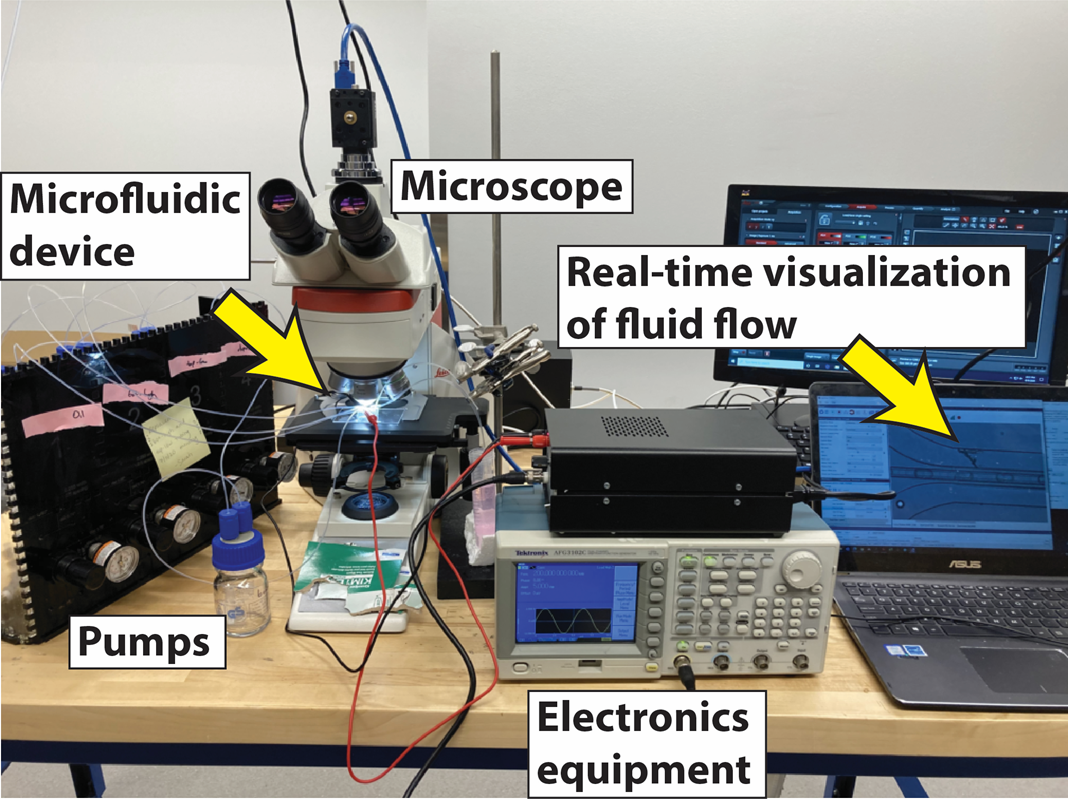

More specifically, the devices that I create involve generating water microdroplets in a surrounding oil phase, and flowing these droplets through a fluid transfer region to add fluid into every flowing droplet. A representative microscope image from a typical experiment is shown here:

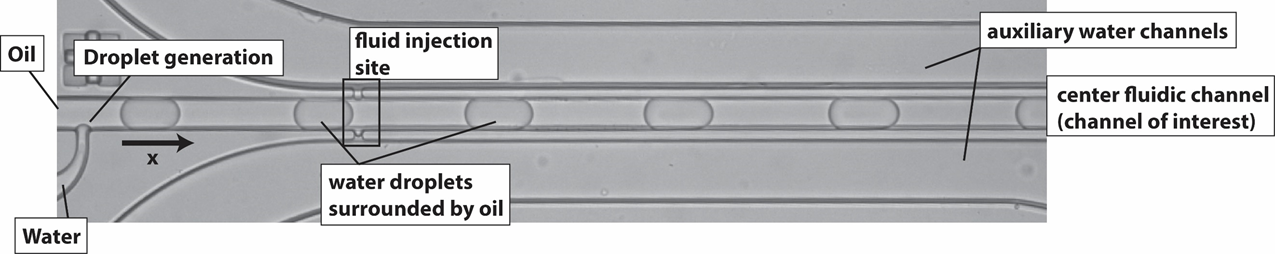

The image files associated with this homework (`Image1.tif, ... , Image19.tif`) are similar to the above and are "snapshots" of the positions and sizes of multiple droplets in the devices at different time points. For example, the above image depicts five different droplets (and part of a sixth) flowing through the center channel of my device. 

**Problem statement**. In this example experiment, I am interested in injecting *very small, precise volumes* into the flowing microdroplets. Using image processing techniques on all of the provided images, **produce a plot that depicts droplet length vs. the position of the droplet** *along the length of the channel (the "x" dimension in the above figure)*. **Use your image processing results to estimate the average volume of fluid injected into the droplets.**

**Tips, hints, and more information:**

- In the images provided, 1 pixel corresponds to 1.07 micrometers.

- The center fluidic channel is the channel that we are interested in for this problem. It has a width of **50 micrometers** and a height of **60 micrometers**.

- The **image processing toolbox** may be useful for this problem. In Lecture 20, we used functions `bwlabel`, `imfill`, and `regionprops` provided in that toolbox.

- Signal processing techniques, such as **filtering** and **thresholding** (creating a binary image using a `<` or `>` operator), may also be useful.

- As an experimentalist, I design my setup so that in the final images, I know which pixels correspond to the center channel of interest, and which correspond to other parts of a device (and are thus not important). In the images provided, **the center channel corresponds to ****rows** `150-199` of the imported "image matrices."

- I recommend that you start small and build up to analyzing all 19 images. That is, refine your algorithm on just one image and use `imshow()` to view the effects of your image processing computations.

- Feel free to create any algorithm you would like to solve this problem. If it helps, *one way* to approach this problem may be to **1)** apply a 2D mean filter to slightly blur the image, **2)** apply a threshold so that each droplet (in a given image) is an individual binary object, and **3)** use `bwlabel`, `imfill`, and `regionprops` to obtain positional and size information about each droplet.

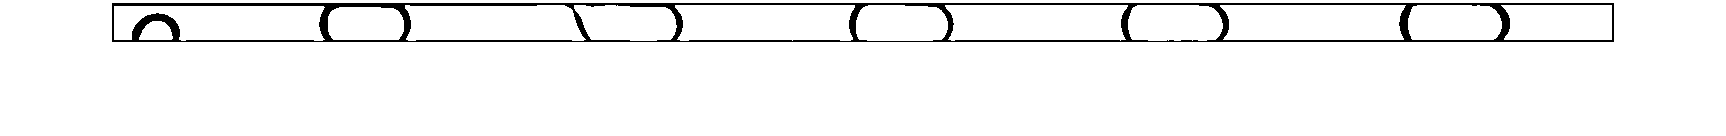

lengths = [];
positions = [];
images = {'Image1.tif','Image2.tif' ,'Image3.tif', 'Image4.tif', 'Image5.tif', 'Image6.tif', 'Image7.tif', 'Image8.tif', 'Image9.tif', 'Image10.tif', 'Image11.tif', 'Image12.tif', 'Image13.tif', 'Image14.tif', 'Image15.tif', 'Image16.tif', 'Image17.tif', 'Image18.tif', 'Image19.tif'};
for k = 1:19
    image = imread(images{k});
    imX = image(152:190, 1:end, :);
    B =ones(5);
    B = B/sum(B,'all');
    imX_filt = filter2(B, imX);


    imX_filt = uint8(imX_filt);
    %imshow(imX_filt)
    imX_bw = imX_filt>140;
    imshow(imX_bw);
    [L, num] = bwlabel(imX_bw);
    
   
   
   
  %1 to the max to the max of L
    for i = 1:num
        obj = regionprops(L == i, 'all');
        %check if it is a droplet based on the circularity and area
        if obj.Circularity > 0.7 && obj.Area >1000
            %convert from pixels
            lengths(end+1) = 1.07*obj.MajorAxisLength;
            positions(end+1) = 1.07*obj.Centroid(1)-0.5*obj.MajorAxisLength;
        end
    end
    
    
end

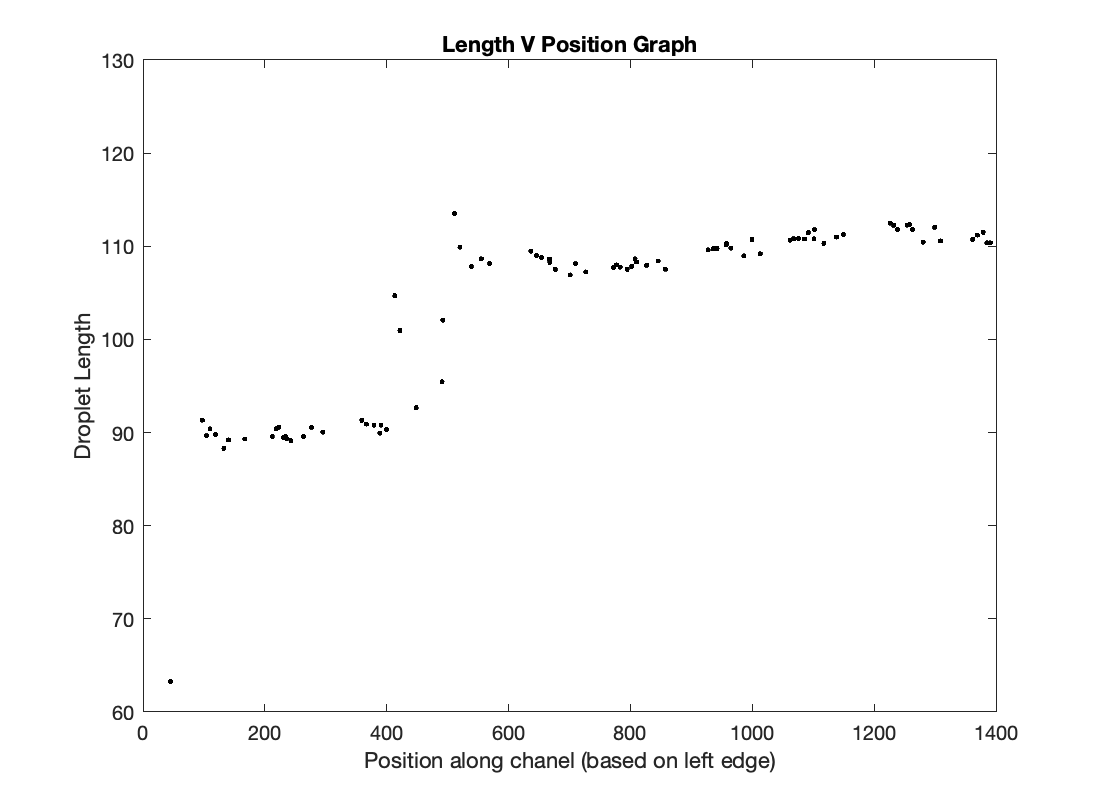

plot(positions,lengths, 'k.')
x0=10;
y0=10;
width=550;
height=400;
xlim([0,1400]);
ylim([60,130])
ylabel('Droplet Length')
xlabel('Position along chanel (based on left edge)')
title('Length V Position Graph')
set(gcf,'position',[x0,y0,width,height])

%to find average volume 


after = lengths(positions>500 & positions<1500);
before = lengths(positions<500);
%if centriod is between 500 and 1500 then it is before that 
volumeInt = 50*60*before;
volumeFinal = 50*60*after;

avgVolumeInt = sum(volumeInt) / length(volumeInt);
avgVolumeFinal = sum(volumeFinal)/ length(volumeFinal);
avgVolumeDrop = (avgVolumeFinal - avgVolumeInt)/1000

avgVolumeDrop = 61.6165

Your plot may look similar to the following.